# Tema lab 1

**Pb 5. **Deduceti seria Taylor pentru ln(1+x) si aproximati ln 2 folosind primii 8 termeni. Cati termeni sunt necesari pentru a obtine ln 2 cu 5 zecimalecorecte? La fel pentru ln (1+x/1-x) .

syms x f g n rest(k) k
f = log(1 + x);
n = 8;
Tnf = taylor(f, x, 'Order', n + 1)

$$Tnf = -\frac{x^{8}}{8}+\frac{x^{7}}{7}-\frac{x^{6}}{6}+\frac{x^{5}}{5}-\frac{x^{4}}{4}+\frac{x^{3}}{3}-\frac{x^{2}}{2}+x$$

f = vpa(subs(Tnf, x, 1))

$$f = 0.63452380952380952380952380952381$$

log2 = vpa(log(2))

$$log2 = 0.69314718055994528622676398299518$$

assume(k > 0);
rest(k) = 1 / (k + 1);
n_minim = solve(rest(k) <= 1e-5, k)

$$n\_minim = 100000$$


g = log((1 + x)/(1 - x));
n = 8;
Tng = taylor(g, x, 'Order', n + 1)

$$Tng = \frac{2\,x^{7}}{7}+\frac{2\,x^{5}}{5}+\frac{2\,x^{3}}{3}+2\,x$$

y = solve((1 + x)/(1 - x) == 2)

$$y = \frac{1}{3}$$

g = vpa(subs(Tng, x, y))

$$g = 0.69313475733228819648572734992488$$

log2

$$log2 = 0.69314718055994528622676398299518$$

% care e g derivat de n ori?

**Pb 7. **Aproximare cu serii MacLaurin

clear();
syms x f
f = exp(x);
T2f = taylor(f, x, 'Order', 3)

$$T2f = \frac{x^{2}}{2}+x+1$$

T3f = taylor(f, x, 'Order', 4)

$$T3f = \frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

T4f = taylor(f, x, 'Order', 5)

$$T4f = \frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

T5f = taylor(f, x, 'Order', 6)

$$T5f = \frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

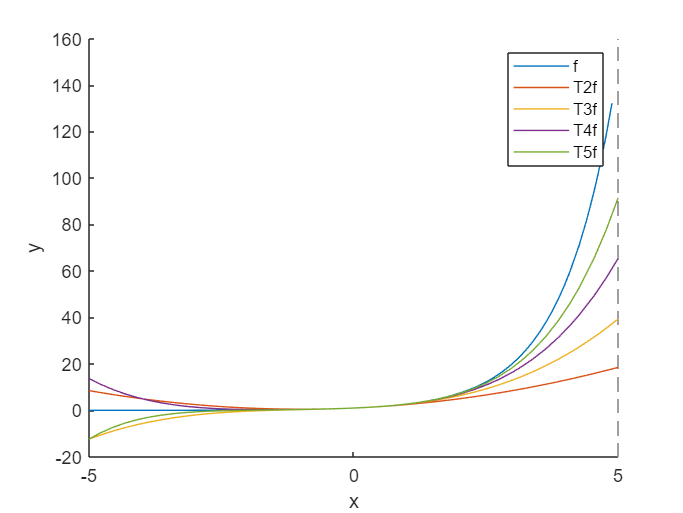


figure;
hold on;
fplot([f, T2f, T3f, T4f, T5f], [-5 5])
legend('f', 'T2f', 'T3f', 'T4f', 'T5f'); 
xlabel('x');
ylabel('y');

Cu cat creste n, observam ca aproximarea se apropie de valoarea functiei.

clear();
syms x g
g = log(1 + x);
T2g = taylor(g, x, 'Order', 3)

$$T2g = x-\frac{x^{2}}{2}$$

T3g = taylor(g, x, 'Order', 4)

$$T3g = \frac{x^{3}}{3}-\frac{x^{2}}{2}+x$$

T4g = taylor(g, x, 'Order', 5)

$$T4g = -\frac{x^{4}}{4}+\frac{x^{3}}{3}-\frac{x^{2}}{2}+x$$

T5g = taylor(g, x, 'Order', 6)

$$T5g = \frac{x^{5}}{5}-\frac{x^{4}}{4}+\frac{x^{3}}{3}-\frac{x^{2}}{2}+x$$

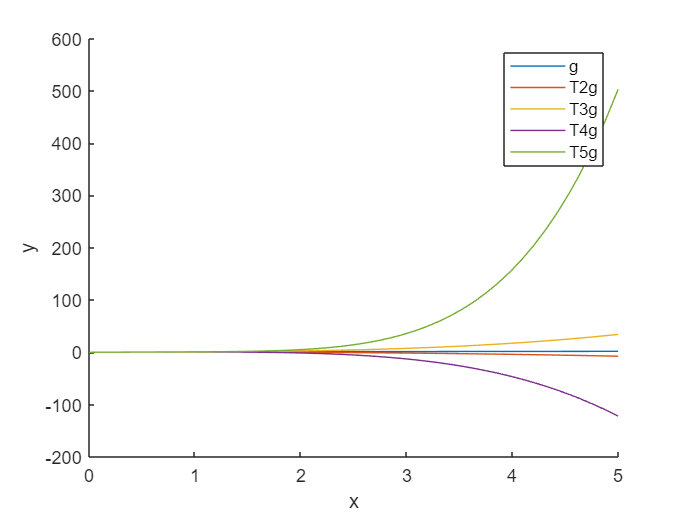


figure;
hold on;
fplot([g, T2g, T3g, T4g, T5g], [0 5])
legend('g', 'T2g', 'T3g', 'T4g', 'T5g'); 
xlabel('x');
ylabel('y');
hold off;

Se observa ca odata cu cresterea lui n, aproximarea noastra se departeaza de graficul functie. (Oare pentru ca este serie alternanta?)

**Pb 8. **Aproximare Pade rationala

b) Testare pt exp(x) - aproximeaza foarte bine, mai bine ca seriile MacLaurin

clear();
syms x f m k
f = exp(x);
R11 = myPadeApprox(f, 1, 1, x)

$$R11 = -\frac{\frac{x}{2}+1}{\frac{x}{2}-1}$$

R22 = myPadeApprox(f, 2, 2, x)

$$R22 = \frac{\frac{x^{2}}{12}+\frac{x}{2}+1}{\frac{x^{2}}{12}-\frac{x}{2}+1}$$

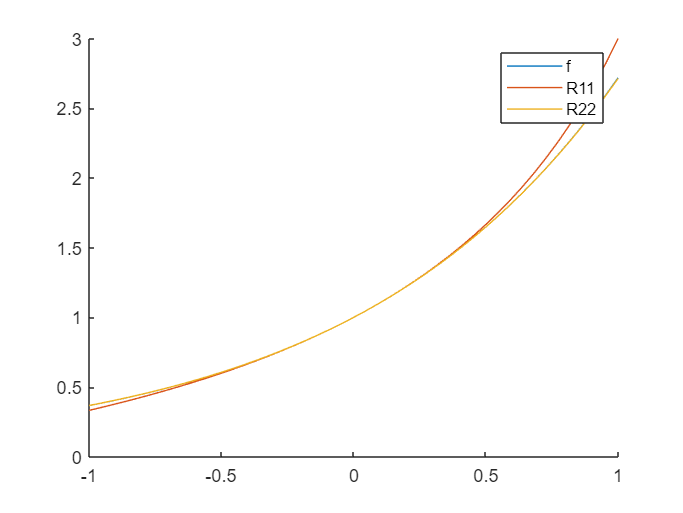


figure;
hold on;
fplot([f, R11, R22], [-1, 1])
legend('f', 'R11', 'R22');
hold off;

c) ln(1 + x)

clear();
syms x f m k
f = log(1 + x);
R22 = myPadeApprox(f, 2, 2, x)

$$R22 = \frac{\frac{x^{2}}{2}+x}{\frac{x^{2}}{6}+x+1}$$

R31 = myPadeApprox(f, 3, 1, x)

$$R31 = \frac{-\frac{x^{3}}{24}+\frac{x^{2}}{4}+x}{\frac{3\,x}{4}+1}$$

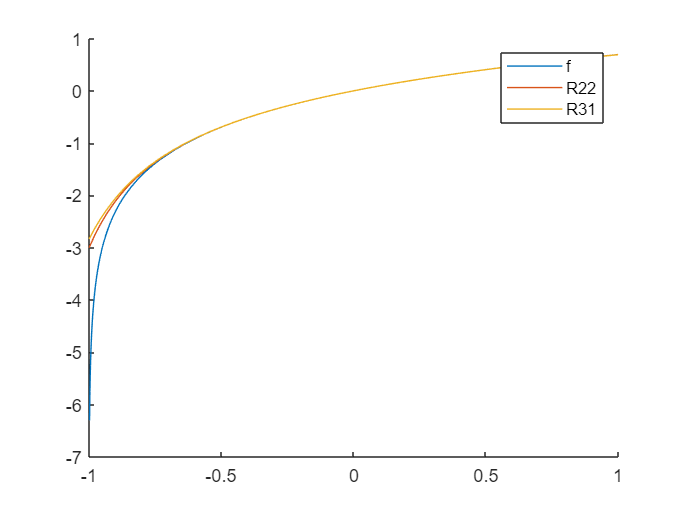


figure;
hold on;
fplot([f, R22, R31], [-1, 1])
legend('f', 'R22', 'R31');
hold off;

a) Implementare

function R = myPadeApprox(f, m, k, x)
first = zeros(k, k, 'sym');
for i = 1:k
    for j = 1:k
        % minunea
        tmp = m + i - j;
        if tmp > 0
            first(i, j) = subs(diff(f, x, tmp), 0) / factorial(tmp);
        end
    end
end
first;

third = zeros(k, 1, 'sym');
for i = 1:k
    tmp = m + i;
    third(i) = - subs(diff(f, x, tmp), 0) / factorial(tmp);
end
third;

bs =zeros(max(m, k) + 1,1,'sym');
bs(2:k+1) = first \ third;
bs(1) = 1;
bs = bs';

syms j
for j = 0:m
    as(j + 1) = sym('0');
    for l = 0:j
        tmp = j - l;
        as(j + 1) = as(j + 1) + (subs(diff(f, x, tmp), 0) / factorial(tmp)) * bs(l + 1);
    end
end
as;

p = sym('0');
for i = 0:m
    p = p + as(i + 1) * x^i;
end

q = sym('0');
for j = 0:k
    q = q + bs(j + 1) * x^j;
end

R = p / q;
end